## parameters

w = 1;
a = 0.2; %0.165
b = 0.2; %0.2
c = 5.7;
x(1)=1;
y(1)=1;
z(1)=1;
h=0.01;
n = 3e6;

## RK-4


for i=1:n
    K1=-(w*y(i)+z(i));
    L1=w*x(i)+a*y(i);
    M1=b+x(i)*z(i)-c*z(i);

    K2=-((y(i)+h/2*L1)+(z(i)+h/2*M1));
    L2=(x(i)+h/2*K1)+a*(y(i)+h/2*L1);
    M2=b+(x(i)+h/2*K1)*(z(i)+h/2*M1)-c*(z(i)+h/2*M1);

    K3=-((y(i)+h/2*L2)+(z(i)+h/2*M2));
    L3=(x(i)+h/2*K2)+a*(y(i)+h/2*L2);
    M3=b+(x(i)+h/2*K2)*(z(i)+h/2*M2)-c*(z(i)+h/2*M2);

    K4=-((y(i)+h*L3)+(z(i)+h*M3));
    L4=(x(i)+h*K3)+a*(y(i)+h*L3);
    M4=b+(x(i)+h*K3)*(z(i)+h*M3)-c*(z(i)+h*M3);

    x(i+1)=x(i)+h/6*(K1+2*K2+2*K3+K4);
    y(i+1)=y(i)+h/6*(L1+2*L2+2*L3+L4);
    z(i+1)=z(i)+h/6*(M1+2*M2+2*M3+M4);
end
clear K* L* M*


## classical RP(Fig 1 left)

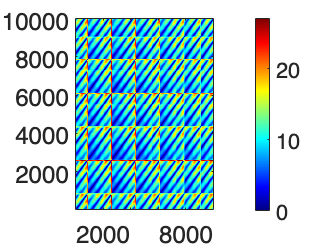

dt = 1;
p = 1e5;
q = p + dt * 1e4;
X = [x(p:dt:q);y(p:dt:q);z(p:dt:q)];
M = X';

d1 = pdist(M);
d1 = squareform(d1);
figure();
imagesc(d1);
colormap('jet');
colorbar;
set(gca,'YDir','normal','FontSize',22);

## Fig1 right

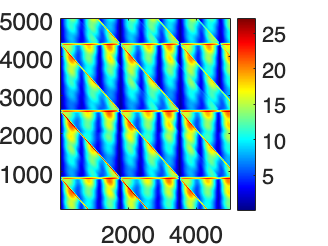

st = 100000;    %start point
len = 5000;
l =5000;        %time span
ed = st+2*l;
m = zeros(len,l);

%cut data
xx = x(st+1:ed);
yy = y(st+1:ed);
zz = z(st+1:ed);

%calculate the distance
for i = 1:l
    for j = 1:l
        m(j,i) = sqrt((xx(i+j)-xx(j))^2 + (yy(i+j)-yy(j))^2 + (zz(i+j)-zz(j))^2);
    end
end


figure()
imagesc(m)
colormap("jet")
colorbar;
%caxis([0,45]);
set(gcf,'Color','White')
set(gca,'YDir','normal','FontSize',22);

## Fig3 A

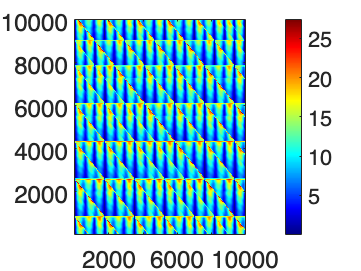

st = 100000;    %start point
len = 10000;
l =10000;        %time span
ed = st+2*l;
m = zeros(len,l);

%cut data
xx = x(st+1:ed);
yy = y(st+1:ed);
zz = z(st+1:ed);

%calculate the distance
for i = 1:l
    for j = 1:l
        m(j,i) = sqrt((xx(i+j)-xx(j))^2 + (yy(i+j)-yy(j))^2 + (zz(i+j)-zz(j))^2);
    end
end


figure()
imagesc(m)
colormap("jet")
colorbar;
%caxis([0,45]);
set(gcf,'Color','White')
set(gca,'YDir','normal','FontSize',22);

## Fig 3B

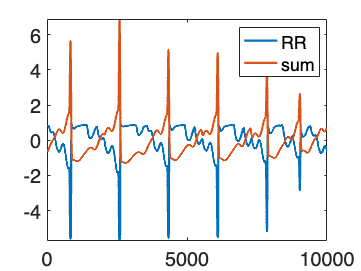

rD = m;
lsum = sum(rD);
hsum = sum(rD');
e = 15;
y1 = [xx;yy;zz]; %classic system
%y1 = xx;       %Epilepsy data
[recur_pt,recur_dist,N_y1,N_y2] = CRP(y1,y1,'RR',e);
for i = 1:length(recur_dist)
    for j = 1:length(recur_dist)
        if recur_dist(i,j) <= e
            recur_dist(i,j) = 1;
        else
            recur_dist(i,j) = 0;
        end
    end
end
RR = sum(recur_dist)./(length(recur_dist) - 1);

len = length(hsum);

figure(3) % fig 3 B
plot(normalize(RR(1:len)),'LineWidth',2)
hold on
plot(normalize(hsum),'LineWidth',2)
xlim([0,len+1])
legend('RR','sum')
set(gcf,'Color','White')
set(gca,'FontSize',18);

corrcoef(normalize(RR(1:len)),normalize(hsum))

ans =    1.000000000000000  -0.954674926637892
  -0.954674926637892   1.000000000000000


## Fig 3 C-D

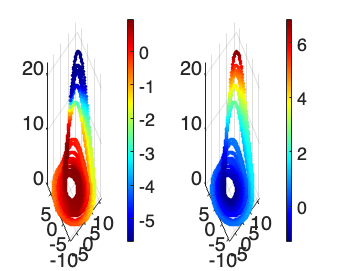

figure(4)
set(gcf,'Color','White')
subplot 121
scatter3(xx(1:len),yy(1:len),zz(1:len),10,normalize(RR(1:len)),"filled")
colormap("jet")
colorbar
set(gca,'FontSize',18);
subplot 122
scatter3(xx(1:len),yy(1:len),zz(1:len),10,normalize(hsum),"filled")
colormap("jet")
colorbar
set(gca,'FontSize',18);

## Fig 4A

l = 200000; %length

aa =   Line - 属性:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1.250000000000000e-07 2.500000000000000e-07 3.750000000000000e-07 5.000000000000000e-07 6.249999999999999e-07 7.500000000000000e-07 8.750000000000000e-07 1.000000000000000e-06 1.125000000000000e-06 1.250000000000000e-06 … ]
              YData: [9.263412951006924e-06 1.851272740890192e-05 2.773369259377007e-05 3.691175745199928e-05 4.603193115005451e-05 5.507865599678078e-05 6.403569640584112e-05 7.288604708494293e-05 8.161186314277487e-05 9.019441425803244e-05 … ]

  显示 所有属性


p = 10000; %start point
dis = zeros(1,l);
dt = 1;
X = x(p:dt:p+(l-1));
Y = y(p:dt:p+(l-1));
Z = z(p:dt:p+(l-1));
for j = 1:l/dt
    dis(j) = sqrt((X(1)-X(j))^2+(Y(1)-Y(j))^2+(Z(1)-Z(j))^2);
end

dt = 1;
Fs = 1/dt;
t = 1:l;
xn = dis;
% apply FFT
frei=40;
NN=l;  xn=xn-mean(xn);
XN=fft(xn,NN*frei)/NN/frei;  
f0=1/(dt*NN*frei);  
f=[0:ceil((NN*frei-1)/2)]*f0;  % Frequency
A=abs(XN);  % Amplitude
B=2*A(1:ceil((NN*frei-1)/2)+1);
figure()
hold on
aa=plot(f(2:end),B(2:end),'b','LineWidth',2)
xlim([0,0.005])
aa.Color(4) = 0.4;
set(gca,'yscale','log')

l = 100000; %length
dis = zeros(1,l);
X = x(p:dt:p+(l-1));
Y = y(p:dt:p+(l-1));
Z = z(p:dt:p+(l-1));
for j = 1:l/dt
    dis(j) = sqrt((X(1)-X(j))^2+(Y(1)-Y(j))^2+(Z(1)-Z(j))^2);
end

dt = 1;
Fs = 1/dt;
t = 1:l;
xn = dis;

frei=40;
NN=l;  
xn=xn-mean(xn);
XN=fft(xn,NN*frei)/NN/frei;  
f0=1/(dt*NN*frei);  
f=[0:ceil((NN*frei-1)/2)]*f0;  
A=abs(XN); 
B=2*A(1:ceil((NN*frei-1)/2)+1);
aa=plot(f(2:end),B(2:end),'r','LineWidth',2)

aa =   Line - 属性:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [2.500000000000000e-07 5.000000000000000e-07 7.500000000000000e-07 1.000000000000000e-06 1.250000000000000e-06 1.500000000000000e-06 1.750000000000000e-06 2.000000000000000e-06 2.250000000000000e-06 2.500000000000000e-06 … ]
              YData: [2.815625558482018e-05 5.623770007956747e-05 8.416954211799316e-05 1.118770345218960e-04 1.392855081530388e-04 1.663204196165930e-04 1.929074170115546e-04 2.189724275781333e-04 2.444417706797238e-04 2.692422990897035e-04 … ]

  显示 所有属性


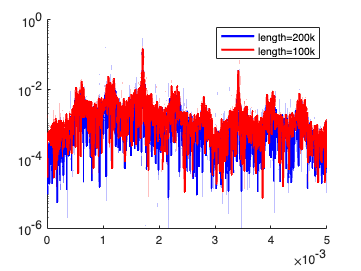

xlim([0,0.005])
aa.Color(4) = 0.4;
xlim([0,0.005])
legend('length=200k','length=100k')

## Fig 4B

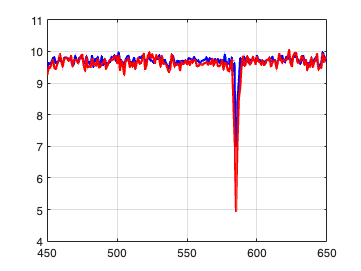

clear ave
figure()
 s = 450:1:650;
 for j = 1:length(s)
    dt = s(j);
    p = 10000;
    q = 210000;
    X = [x(p:dt:q);y(p:dt:q);z(p:dt:q)];
    M = X';
    d2 = pdist(M);
    d1 = squareform(d2);
    ave(j) = sum(sum(d1))/length(d1)/length(d1);  
 end
aa=plot(s,ave,'b','LineWidth',2);
grid on; hold on
aa.Color(4) = 1;

clear ave
 s = 450:1:650;
 for j = 1:length(s)
    dt = s(j);
    p = 10000;
    q = 110000;
    X = [x(p:dt:q);y(p:dt:q);z(p:dt:q)];
    M = X';
    d2 = pdist(M);
    d1 = squareform(d2);
    ave(j) = sum(sum(d1))/length(d1)/length(d1);  
 end
aa=plot(s,ave,'r','LineWidth',2);
grid on; hold on

aa.Color(4) = 1;


## Chaos Degree - confidence interval

% calculate recurrence frequency( PP in manuscipt) 
p_list = [10000:5000:500000];
for ii =1:length(p_list)
    l = 100000; %length
    p = p_list(ii); %start point
    dis = zeros(1,l);
    dt = 1;
    X = x(p:dt:p+(l-1));
    Y = y(p:dt:p+(l-1));
    Z = z(p:dt:p+(l-1));
    for j = 1:l/dt
        dis(j) = sqrt((X(1)-X(j))^2+(Y(1)-Y(j))^2+(Z(1)-Z(j))^2);
    end
    
    dt = h;
    Fs = 1/dt;
    t = 1:l;
    xn = dis;
    % fft
    frei=40;
    NN=l;  
    xn=xn-mean(xn);
    XN=fft(xn,NN*frei)/NN/frei;  
    f0=1/(dt*NN*frei);  
    f=[0:ceil((NN*frei-1)/2)]*f0;  
    A=abs(XN); 
    B=2*A(1:ceil((NN*frei-1)/2)+1);
    
    [max_num,max_idx] = max(B);
    pf = f(max_idx);
    rf = 1/pf;
    RF(ii) = rf;
    
    % get matrix
    n = 5000;
    m = 100;        
    ed = p+2*n;
    mm = zeros(m,n);
    
    %cut data
    xx = x(p+1:ed);
    yy = y(p+1:ed);
    zz = z(p+1:ed);
    
    %calculate the distance
    for i = 1:n
        for j = 1:m
            mm(j,i) = sqrt((xx(i+j)-xx(j))^2 + (yy(i+j)-yy(j))^2 + (zz(i+j)-zz(j))^2);
        end
    end

    n_max = floor(n/rf*h);
    mm=mapminmax(mm);
    
    m2=mm(:,1:round(rf/h));
    mmm = repmat(m2,1,n_max);
    Distances=abs(mmm-mm(:,1:length(mmm)));
    CD(ii) = mean(mean(Distances));
end


mean_value = mean(CD);
std_dev = std(CD);
 
% confidence interval
confidence_interval = norminv(0.975, 0, 1) * std_dev / sqrt(length(CD));
lower_bound = mean_value - confidence_interval;
upper_bound = mean_value + confidence_interval;

fprintf('95%% confidence interval: [%.4f, %.4f]\n', lower_bound, upper_bound);

95% confidence interval: [0.1684, 0.1873]


## chaos degree - sensitivity

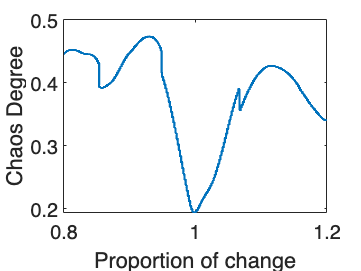

clear rf_list CD

rf_list = [mean(RF)*0.8:0.001:mean(RF)*1.2];
% get matrix
n = 5000;
m = 100;
ed = p+2*n;
mm = zeros(m,n);

%cut data
xx = x(p+1:ed);
yy = y(p+1:ed);
zz = z(p+1:ed);

%calculate the distance
for i = 1:n
    for j = 1:m
        mm(j,i) = sqrt((xx(i+j)-xx(j))^2 + (yy(i+j)-yy(j))^2 + (zz(i+j)-zz(j))^2);
    end
end

for ii = 1:length(rf_list)
    rf = rf_list(ii);
    n_max = floor(n/rf*h);
    mm=mapminmax(mm);
    
    m2=mm(:,1:floor(rf/h));
    mmm = repmat(m2,1,n_max);
    Distances=abs(mmm-mm(:,1:length(mmm)));
    CD(ii) = mean(mean(Distances));
end
figure()
plot(rf_list./mean(RF),CD,'LineWidth',2)
set(gcf,'Color','White')
set(gca,'FontSize',18);
xlabel('Proportion of change')
ylabel('Chaos Degree')

## Fig 5 A-C (load Epilepsy data at first)

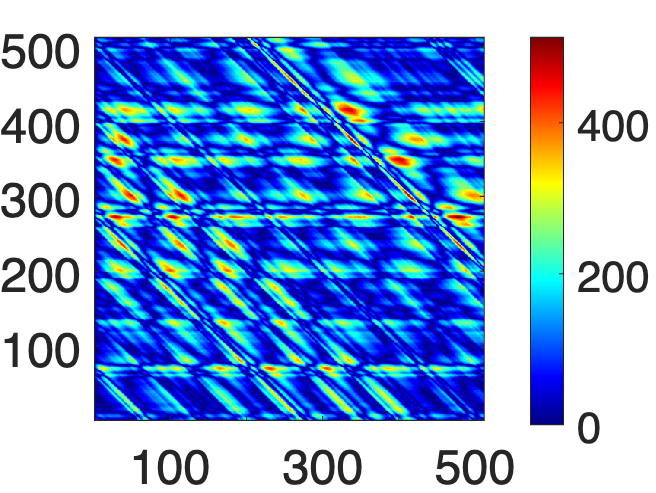

clear m
xx = ictal;
for i = 1:512
    for j = 1:512
        m(j,i) = abs(xx(i+j)-xx(j));
    end
end
figure()
imagesc(m)
colormap("jet")
colorbar;
%caxis([0,45]);
set(gcf,'Color','White')
set(gca,'YDir','normal','FontSize',22);

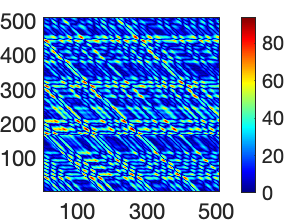


xx = preictal;
for i = 1:512
    for j = 1:512
        m(j,i) = abs(xx(i+j)-xx(j));
    end
end
figure()
imagesc(m)
colormap("jet")
colorbar;
%caxis([0,45]);
set(gcf,'Color','White')
set(gca,'YDir','normal','FontSize',22); 

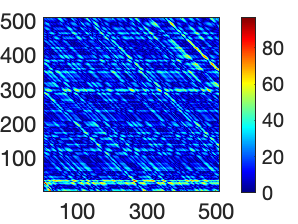


xx = interictal;
for i = 1:512
    for j = 1:512
        m(j,i) = abs(xx(i+j)-xx(j));
    end
end
figure()
imagesc(m)
colormap("jet")
colorbar;
%caxis([0,45]);
set(gcf,'Color','White')
set(gca,'YDir','normal','FontSize',22); 

## Fig 5 D

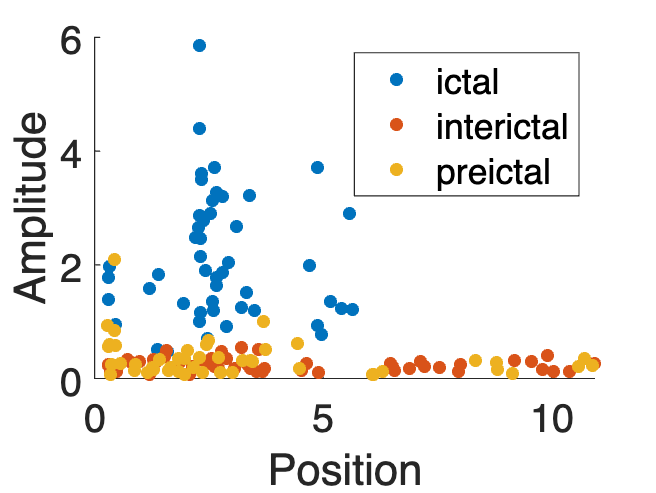

load(pos_val.mat);
% pf and amplitude can be calculated as fig 4A
figure()
scatter(ictal_pos,ictal_val,'filled')
hold on
scatter(inter_pos,inter_val,'filled')
scatter(pre_pos,pre_val,'filled')

set(gca,'FontSize',18); 
xlabel('Position')
ylabel('Amplitude')
set(gcf,'Color','White')
legend('ictal','interictal','preictal')

## Fig 6 A-B

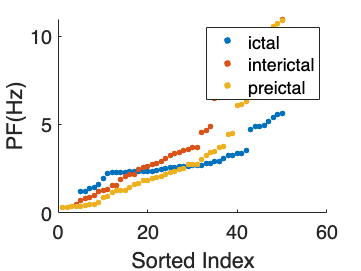

% load(pos_val.mat);
figure()
scatter(1:50,sort(ictal_pos),25,'filled')
hold on
scatter(1:50,sort(inter_pos),25,'filled')
scatter(1:50,sort(pre_pos),25,'filled')
set(gca,'FontSize',18); 
xlabel('Sorted Index')
ylabel('PF(Hz)')
set(gcf,'Color','White')
legend('ictal','interictal','preictal')

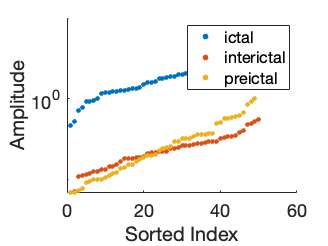


figure()
scatter(1:50,sort(ictal_val),25,'filled')
hold on
scatter(1:50,sort(inter_val),25,'filled')
scatter(1:50,sort(pre_val),25,'filled')
set(gca,'FontSize',18,'yscale','log'); 
xlabel('Sorted Index')
ylabel('Amplitude')
set(gcf,'Color','White')
legend('ictal','interictal','preictal')

## Fig 6C

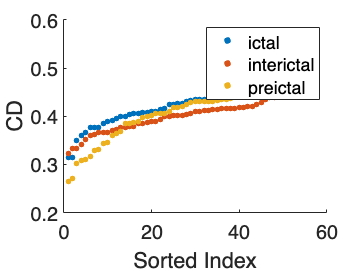

clc,clear
% rf of each stage: ictal 0.36778967-73 inter 0.236151469-47 pre 0.295902445-59
rf = 74;
n_max = floor(512/rf);
CD = zeros(50,n_max-1);
for id = 1:1:50
    load(['.../ictal',num2str(id),'.mat'])
    xx = ictal;
    for i = 1:512
        for j = 1:512
            m(j,i) = abs(xx(i+j)-xx(j));
        end
    end
    for ii = 1:512
        % x = m(ii,:);
        x = m(:,ii);
        mm = (2*(x-min(x)))/(max(x)-min(x))-1;
        m(:,ii) = mm;
        % m(ii,:) = mm;
    end
    d0 = m(:,1:rf);
    for n = 1:n_max-1
        d = m(:,rf*n+1:rf*(n+1));
        cd = mean(mean(abs(d-d0)));
        CD(id,n) = cd;
    end
end
figure()
scatter(1:50,sort(mean(CD')),25,'filled')
hold on
CD_Ictal = sort(mean(CD'));

rf = 47;
n_max = floor(512/rf);
CD = zeros(50,n_max-1);
for id = 1:1:50
    load(['.../interictal',num2str(id),'.mat'])
    xx = interictal;
    for i = 1:512
        for j = 1:512
            m(j,i) = abs(xx(i+j)-xx(j));
        end
    end
    for ii = 1:512
        % x = m(ii,:);
        x = m(:,ii);
        mm = (2*(x-min(x)))/(max(x)-min(x))-1;
        m(:,ii) = mm;
        % m(ii,:) = mm;
    end
    d0 = m(:,1:rf);
    for n = 1:n_max-1
        d = m(:,rf*n+1:rf*(n+1));
        cd = mean(mean(abs(d-d0)));
        CD(id,n) = cd;
    end
end
scatter(1:50,sort(mean(CD')),25,'filled')
CD_Interictal = sort(mean(CD'));

rf = 59;
n_max = floor(512/rf);
CD = zeros(50,n_max-1);
for id = 1:1:50
    load(['.../preictal',num2str(id),'.mat'])
    xx = preictal;
    for i = 1:512
        for j = 1:512
            m(j,i) = abs(xx(i+j)-xx(j));
        end
    end
    for ii = 1:512
        % x = m(ii,:);
        x = m(:,ii);
        mm = (2*(x-min(x)))/(max(x)-min(x))-1;
        m(:,ii) = mm;
        % m(ii,:) = mm;
    end
    d0 = m(:,1:rf);
    for n = 1:n_max-1
        d = m(:,rf*n+1:rf*(n+1));
        cd = mean(mean(abs(d-d0)));
        CD(id,n) = cd;
    end
end
scatter(1:50,sort(mean(CD')),25,'filled')
CD_Preictal = sort(mean(CD'));

set(gca,'FontSize',18); 
xlabel('Sorted Index')
ylabel('CD')
set(gcf,'Color','White')
legend('ictal','interictal','preictal')

## Fig 6D

LE = zeros(50,1);
for id = 1:1:50
    load(['.../ictal',num2str(id),'.mat'])
    xx = ictal;
    % set parameters
    tau = 5; % delay
    dim = 1; % embed
    T = length(xx); % length of data
    
    % calculate LLE
    LE(id) = lyapunov_exponent2(xx, tau, dim, T);
end
figure()
scatter(1:50,sort(LE),25,'filled')
hold on
LLE_Ictal = sort(LE)';

LE = zeros(50,1);
for id = 1:1:50
    load(['.../interictal',num2str(id),'.mat'])
    xx = interictal;
    % set parameters
    tau = 5; % delay
    dim = 1; % embed
    T = length(xx); % length of data
    
    % calculate LLE
    LE(id) = lyapunov_exponent2(xx, tau, dim, T);
end

警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该

scatter(1:50,sort(LE),25,'filled')
LLE_Interictal = sort(LE)';

LE = zeros(50,1);
for id = 1:1:50
    load(['.../preictal',num2str(id),'.mat'])
    xx = preictal;
   % set parameters
    tau = 5; % delay
    dim = 1; % embed
    T = length(xx); % length of data
    
    % calculate LLE
    LE(id) = lyapunov_exponent2(xx, tau, dim, T);
end

警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该点。
警告：出现零或NaN，跳过该

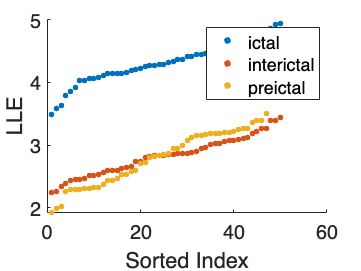

scatter(1:50,sort(LE),25,'filled')
LLE_Preictal = sort(LE)';

set(gca,'FontSize',18); 
xlabel('Sorted Index')
ylabel('LLE')
set(gcf,'Color','White')
legend('ictal','interictal','preictal')

## T-test

% do T_test to LLE and CD
[h_Ictal, p_Ictal] = ttest(LLE_Ictal, CD_Ictal);
[h_Preictal, p_Preictal] = ttest(LLE_Preictal, CD_Preictal);
[h_Interictal, p_Interictal] = ttest(LLE_Interictal, CD_Interictal);

% output
fprintf('Ictal t-test: h = %.2f, p = %.4f\n', h_Ictal, p_Ictal);

Ictal t-test: h = 1.00, p = 0.0000


fprintf('Preictal t-test: h = %.2f, p = %.4f\n', h_Preictal, p_Preictal);

Preictal t-test: h = 1.00, p = 0.0000


fprintf('Interictal t-test: h = %.2f, p = %.4f\n', h_Interictal, p_Interictal);

Interictal t-test: h = 1.00, p = 0.0000


## periodic signals with more than one periodicity (ECG data)

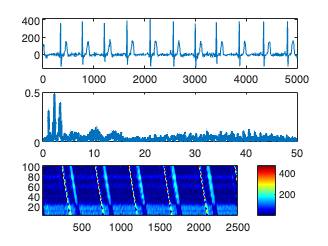

ind_list = 7;
for kk = 1:length(ind_list)
    ind = ind_list(kk);
    data = csvread(['F',num2str(ind),'.csv']);
end

X=data(:,1);
subplot 311
plot(X)

%% calculate rf 

    l=length(X);
    for j = 1:l
        dis(j) = abs(X(1)-X(j));
    end
    
    Fs = 500;
    dt = 1/Fs;
    t = 1:l;
    xn = dis;
    
    frei=40;
    NN=l;  
    xn=xn-mean(xn);
    XN=fft(xn,NN*frei)/NN/frei;  
    f0=1/(dt*NN*frei);  
    f=[0:ceil((NN*frei-1)/2)]*f0;  
    A=abs(XN); 
    B=2*A(1:ceil((NN*frei-1)/2)+1);
    subplot 312
    aa=plot(f(2:end),B(2:end),'LineWidth',2);
    xlim([0,50])
    [max_num,max_idx] = max(B);
    pf = f(max_idx);
    rf = 1/pf;

%% get matrix
    n = 2500;
    m = 100;        
    ed = 2*n;
    mm = zeros(m,n);
    
    %cut data
    xx = data(1:ed);
    
    %calculate the distance
    for i = 1:n
        for j = 1:m
            mm(j,i) = abs(xx(i+j)-xx(j));
        end
    end

    subplot 313
    imagesc(mm)
    colormap("jet")
    colorbar;
    %caxis([0,45]);
    set(gcf,'Color','White')
    set(gca,'YDir','normal');


    n_max = floor(n/rf*dt);
    mm=mapminmax(mm);
    
    m2=mm(:,1:round(rf/dt));
    mmm = repmat(m2,1,n_max);
    Distances=abs(mmm-mm(:,1:length(mmm)));
    CD = mean(mean(Distances));

    fprintf('RF= %.4f\n', rf);

RF= 0.4444


    fprintf('CD= %.4f\n', CD);

CD= 0.1380


## noise

% calculate rf
l = 100000; %length
p = 10000; %start point
dis = zeros(1,l);
dt = 1;
% add noise
X = x(p:dt:p+(l-1))+rand(1,l);
Y = y(p:dt:p+(l-1))+rand(1,l);
Z = z(p:dt:p+(l-1))+rand(1,l);
for j = 1:l/dt
    dis(j) = sqrt((X(1)-X(j))^2+(Y(1)-Y(j))^2+(Z(1)-Z(j))^2);
end

dt = h;
Fs = 1/dt;
t = 1:l;
xn = dis;

frei=40;
NN=l;
xn=xn-mean(xn);
XN=fft(xn,NN*frei)/NN/frei;
f0=1/(dt*NN*frei);
f=[0:ceil((NN*frei-1)/2)]*f0;
A=abs(XN);
B=2*A(1:ceil((NN*frei-1)/2)+1);

[max_num,max_idx] = max(B);
pf = f(max_idx);
rf = 1/pf;

% get matrix
n = 5000;
m = 100;
ed = p+2*n;
mm = zeros(m,n);

%calculate the distance
for i = 1:n
    for j = 1:m
        mm(j,i) = sqrt((X(i+j)-X(j))^2 + (Y(i+j)-Y(j))^2 + (Z(i+j)-Z(j))^2);
    end
end

n_max = floor(n/rf*h);
mm=mapminmax(mm);

m2=mm(:,1:round(rf/h));
mmm = repmat(m2,1,n_max);
Distances=abs(mmm-mm(:,1:length(mmm)));
CD = mean(mean(Distances));

fprintf('RF= %.4f\n', rf);

RF= 5.8557


fprintf('CD= %.4f\n', CD);

CD= 0.1826
